% The following code simulates the forward kinematics of a simple 2DOF
% serial manipulator. Figure 2 shows its movement from start to end
% position, Figure 1 shows the location of its end effector at points of
% its trajectory and Figure 3 shows the maximum potential workspace of the
% arm's end effector.

d1 = 0.079;
L1 = 0.121;
L2 = 0.121;
L3 = 0.142;


syms q1 q2 q3 q4 q5;

Q1 = q1*180/pi;
Q2 = q2*180/pi;
Q3 = q3*180/pi;
Q4 = q4*180/pi;
Q5 = q5*180/pi;

T_12 = create_T_ij_matrice(0,90,d1,Q1);
T_23 = create_T_ij_matrice(L1,0,0,Q2);
T_34 = create_T_ij_matrice(L2,0,0,Q3);
T_45 = create_T_ij_matrice(0,-90,0,Q4);
T_56 = create_T_ij_matrice(0,0,L3,Q5);

sympref('AbbreviateOutput',false)

ans = logical
   0


T_16 = T_12*T_23*T_34*T_45*T_56


T_13 = T_12*T_23;
clear all
close all
clc
disp('The following code simulates the forward kinematics of a simple 2DOF')

The following code simulates the forward kinematics of a simple 2DOF


disp('serial manipulator. Figure 2 shows its movement from start to end position,')

serial manipulator. Figure 2 shows its movement from start to end position,


disp('Figure 1 shows the location of its end effector at points of its trajectory')

Figure 1 shows the location of its end effector at points of its trajectory


disp('and Figure 3 shows the maximum potential workspace of its end effector')

and Figure 3 shows the maximum potential workspace of its end effector


## A series of joint angles

The following variables are defined in the form of column-vectors with 4 rows each. Each row represents a different position (angle) of the joint. e.g. inititally we hae 60 degrees for q1 and -30 for q2.

q1 = [0 45 90 135]'*pi/180 ;
q2 = [-45  0  45  90]'*pi/180 ;
q3 = [-45  0  45  90]'*pi/180 ;
q4 = [-45  0  45  90]'*pi/180 ;
q5 = [-45  0  45  90]'*pi/180 ;
q = [ q1 q2 q3 q4 q5 ] ;

## Links Lengths

l1 = 0.1 ;
l2 = 0.1 ;

## Trigonometric abbreviations

c1 = cos(q1);
c2 = cos(q2);
c12 = cos(q1+q2);

s1= sin(q1);
s2 = sin(q2);
s12 = sin(q1+q2)

## Tip position

These equations are derived from the Forward Kinematic model of the 2DOF robot

xt = cos(q1)*cos(q2)-cos(q4)*(cos(q1)*cos(q2)*sin(q3)+cos(q1)*cos(q3)*sin(q2))-sin(q4)*(cos(q1)*cos(q2)*cos(q3)-cos(q1)*sin(q2)*sin(q3))+cos(q1)*cos(q2)*cos(q3)-cos(q1)*sin(q2)*sin(q3);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation

yt = cos(q2)*sin(q1)-cos(q4)*(cos(q2)*sin(q1)*sin(q3)+cos(q3)*sin(q1)*sin(q2))+sin(q4)*(sin(q1)*sin(q2)*sin(q3)-cos(q2)*cos(q3)*sin(q1))-sin(q1)*sin(q2)*sin(q3)+cos(q2)*cos(q3)*sin(q1);
zt = sin(q2)+cos(q2)*sin(q3)+cos(q3)*sin(q2)+cos(q4)*(cos(q2)*cos(q3)-sin(q2)*sin(q3))-sin(q4)*(cos(q2)*sin(q3)+cos(q3)*sin(q2))+1;

pt = [ xt yt ] ;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot the trajectory of the end-effector

figure (1)
set(1,'position',[680 558 560 420])

plot3(pt(1,1),pt(1,2),0,'rx')       % plot the first position of the robot's end effector
hold on
plot(pt(2:4,1),pt(2:4,2),'x')       % plot the 3 following positions of the robot's end effector
title('Tip Trajectory') ; xlabel('x (m)') ; ylabel('y (m)') ;

## Plot the robotic arm, in 4 different positions

figure (2) 
set(2,'position',[116 190 560 420])

x1 = zeros(4,1) ;
y1 = zeros(4,1) ;

x2 = l1*c1 ;
y2 = l1*s1 ;


for i = 1:4
    xx = [ x1(i); x2(i); pt(i,1) ] ;
    yy = [ y1(i); y2(i); pt(i,2) ] ;
    
    plot(xx,yy,'ko-','Linewidth',2)
    axis equal
    hold on
        
    xlabel('x (m)') ; ylabel('y (m)') ;
    text(pt(1,1),pt(1,2),'x') ; text(pt(1,1) + 0.002,pt(1,2) + 0.002,'ptStart') ;
    text(pt(4,1),pt(4,2),'x') ; text(pt(4,1) + 0.002,pt(4,2) + 0.002,'ptEnd') ;
    axis([-0.07 0.15 -0.01 0.18])
    pause(0.05)
    hold off
    pause(0.1)
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Workspace

q1 = 0:pi/180:2*pi-pi/180 
q2 = 0:pi/180:2*pi-pi/180
q3 = 0:pi/180:2*pi-pi/180


cw1 = cos(q1)
sw1 = sin(q1)
cw12 = zeros(360,360) 
sw12 = zeros(360,360);

## Plot the workspace of the robot

step = 360/20;
nb_points = round(360/step);
%disp(nb_points);
%disp(nb_points^3);
xwork = zeros(nb_points^2) ; % reserving space for the variables, because
ywork = zeros(nb_points^2) ; % otherwise they would be created later within a loop.
zwork = zeros(nb_points^2);
i=1;
q5 = 0;
max = 0;

for q1 = 0:step:360
    for q2 = 0:step:180
        for q3 = -65:step:115
            for q4 = -180:step:0
                L_q = [q1 q2 q3 q4 q5];
                pos = forward_kinematics(L_q);
                if (pos(1)^2+pos(2)^2+pos(3)^2)^0.5 >0
                    max = (pos(1)^2+pos(2)^2+pos(3)^2)^0.5;
                    xwork(i) = pos(1);
                    ywork(i) = pos(2);
                    zwork(i) = pos(3);
                    i = i+1;
                end
            end
        end
    end
end    


figure (3)
set(3,'position')

  0×0 empty cell array



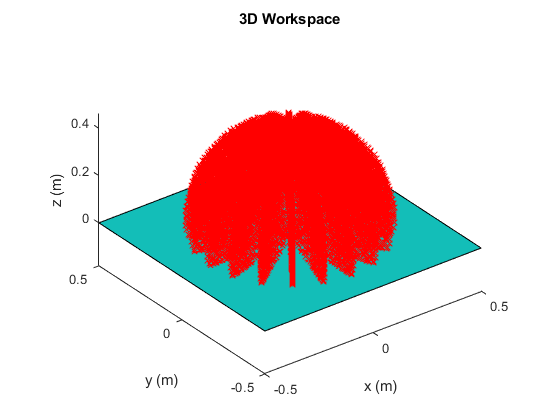

plot3(0,0,0,'o')
hold on
[xp, yp] = meshgrid(-0.5:1:0.5); % Generate x and y data
zp = zeros(size(xp, 1)); % Generate z data
surf(xp, yp, zp) % Plot the surface
plot3(xwork,ywork,zwork,'rx')  % plot the  workspace of the robot
axis equal

title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
hold off

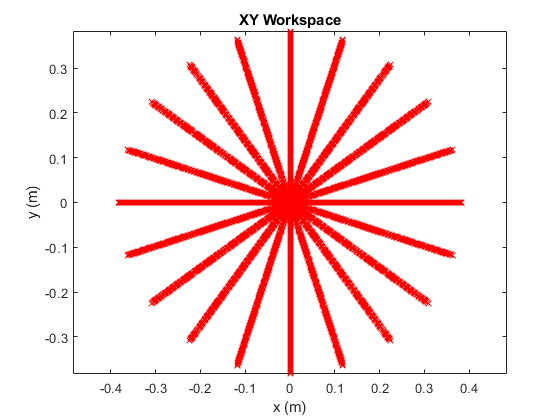



plot(xwork,ywork,'rx')
title('XY Workspace') ; xlabel('x (m)') ; ylabel('y (m)');
axis equal

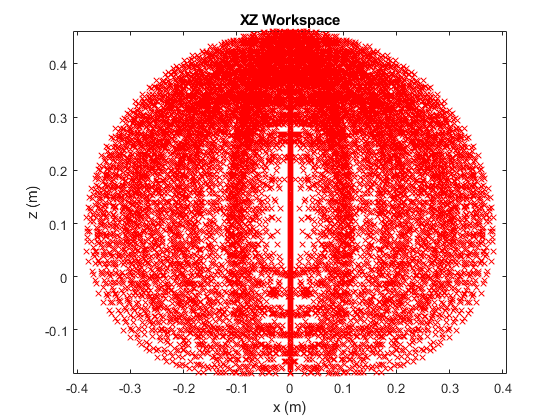




plot(xwork,zwork,'rx')
title('XZ Workspace') ; xlabel('x (m)') ; ylabel('z (m)');
axis equal

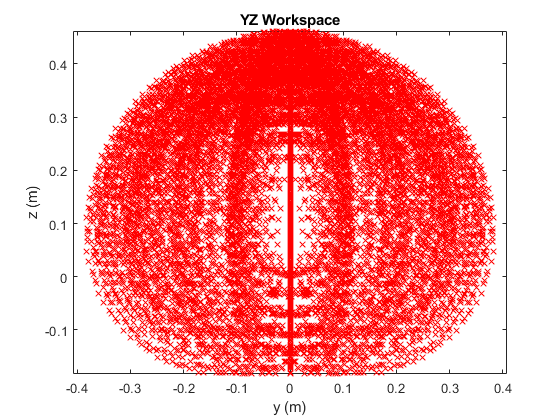



plot(ywork,zwork,'rx')
title('YZ Workspace') ; xlabel('y (m)') ; ylabel('z (m)');
axis equal

## Inverse Kinematics

inv_mat=inverse_kin(0,0,0.463,90,0)

Error using atan2
Inputs must be real.

Error in inverse_kin (line 19)
theta3 = atan2((z_prime-L1*sin(theta2))/L2,(rho_prime-L1*cos(theta2))/L2)-theta2;